# Herramientas Matemáticas  

### Ejercicio 1

Grafique el sistema {𝑀} respecto de {𝑂} para cada una de las siguientes matrices  de rotación:  

a. $\degree {\textrm{Rot}}_M =\left\lbrack \begin{array}{cc}
0\ldotp 5 & -0\ldotp 866\\
0\ldotp 866 & 0\ldotp 5
\end{array}\right\rbrack$

Esta matriz de rotación es lo mismo que ${\textrm{Rot}}_Z \left(\frac{\pi }{3\;}\right)$.

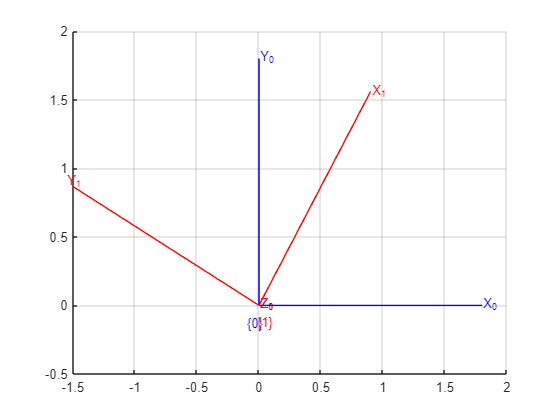

clear; close all;
T0 = eye(3);
T1 = [0.5 -0.866 0; 0.866 0.5 0; 0 0 1];

figure
hold on
trplot(T0,'color','b','frame','0','length',1.8)
trplot(T1,'color','r','frame','1','length',1.8)    

grid on
axis([-1.5 2 -.5 2 -2 2])
view(0,90)

b. ${\degree \textrm{Rot}}_M =\left\lbrack \begin{array}{ccc}
0 & 0 & 1\\
-1 & 0 & 0\\
0 & -1 & 0
\end{array}\right\rbrack$

Esta matriz de rotación es lo mismo que ${\textrm{Rot}}_{Y_1 } \left(-\pi \right)\to {\textrm{Rot}}_{Z_1 } \left(-\pi \;\right)$.

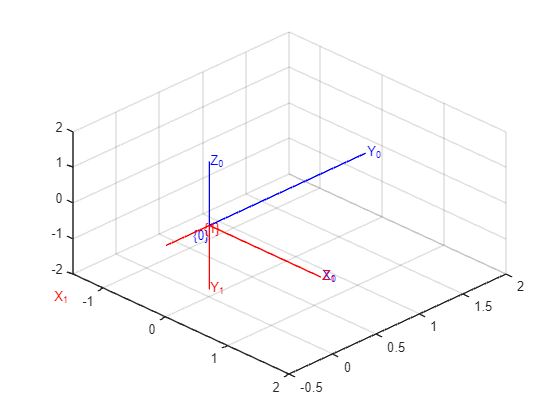

T2 = eye(4);
T3 = [0 0 1 0; -1 0 0 0; 0 -1 0 0; 0 0 0 1];

figure
hold on
trplot(T2,'color','b','frame','0','length',1.8)
trplot(T3,'color','r','frame','1','length',1.8)    
grid on
axis([-1.5 2 -.5 2 -2 2])
view(45,45)

c. $\degree {\textrm{Rot}}_M =\left\lbrack \begin{array}{ccc}
0\ldotp 50 & -0\ldotp 75 & -0\ldotp 433\\
0\ldotp 866 & 0\ldotp 433 & 0\ldotp 25\\
0 & -0\ldotp 5 & 0\ldotp 866
\end{array}\right\rbrack$

T4 = eye(4);
T5 = [0.5 -0.75 -0.433 0; 0.866 0.433 0.25 0; 0 -0.5 0.866 0; 0 0 0 1];

figure
hold on
trplot(T4,'color','b','frame','0','length',1.8)
trplot(T5,'color','r','frame','1','length',1.8)    

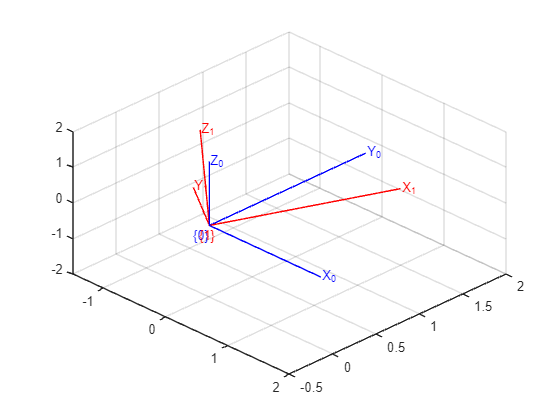

grid on
axis([-1.5 2 -.5 2 -2 2])
view(45,45)

Se recomienda usar el toolbox de “rtb” de Peter Corke para Matlab. 

### Ejercicio 2 (obligatorio)

Exprese cada uno de los siguientes vectores en el sistema de  referencia {𝑂} sabiendo que sus coordenadas son respecto al sistema {𝑀}, el cual sufrió la  rotación indicada. Realice un gráfico donde se aprecie el vector y sus coordenadas en ambos  sistemas.  

a. ${}^{M}a = $$\left\lbrack \begin{array}{cc}
1 & 0\ldotp 5
\end{array}\right\rbrack$; {M} rotó de -17° en $Z_O$


$$\degree a=$$


clear; close all;
T0 = eye(3);
T1 = rotz(-0.297);
am=[1; 0.5; 0];
a0=T1*am;
figure;
hold on;
trplot(T0,'color','b','frame','0','length',1.8)
trplot(T1,'color','r','frame','1','length',1.8)
plot_arrow([0, 0, 0], [a0(1),a0(2),a0(3)])

grid on
axis([-1.5 2 -.5 2 -2 2])
axis equal;
view(0,90)


b. ${}^{M}b
$$=\left\lbrack \begin{array}{ccc}
0 & 0 & 1
\end{array}\right\rbrack$ {M} rotó de 35° en $Y_O$


$$\degree b=$$


clear; close all;
T2  =eye(3);
T3 = roty(0.61087);
bm=[0; 0; 1;];
b0=T3*bm

b0 =     0.5736
         0
    0.8191


figure 
hold on
trplot(T2,'color','b','frame','0','length',1.8)
trplot(T3,'color','r','frame','1','length',1.8)
plot_arrow([0, 0, 0], [b0(1),b0(2),b0(3)])

grid on
axis([-1.5 2 -.5 2 -2 2])
axis equal;
view(0,0)


c. ${}^{M}c$$=\left\lbrack \begin{array}{ccc}
1 & 0\ldotp 5 & 0\ldotp 3
\end{array}\right\rbrack$ {M} rotó de 90° en $Y_O$

clear; close all;
T4 = eye(3);
T5 = roty(3.1416/2);
cm=[1; 0.5;0.3];
c0=T5*cm;
figure 
hold on
trplot(T4,'color','b','frame','0','length',1.8)
trplot(T5,'color','r','frame','1','length',1.8)
plot_arrow([0, 0, 0], [c0(1),c0(2),c0(3)])

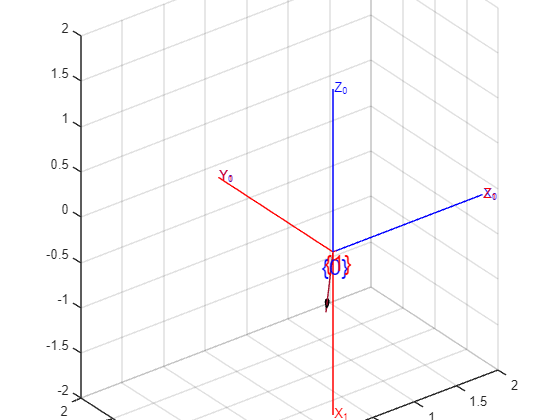

grid on
axis([-1.5 2 -.5 2 -2 2])
axis equal;
view(3)

### Ejercicio 3

Escriba en forma general las matrices de transformación homogénea que  representan los siguientes casos:  

a. Traslación pura en el espacio  

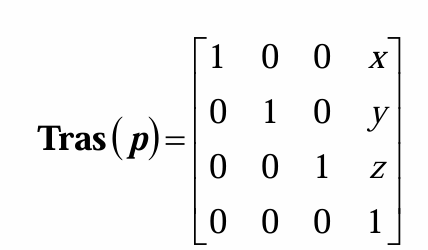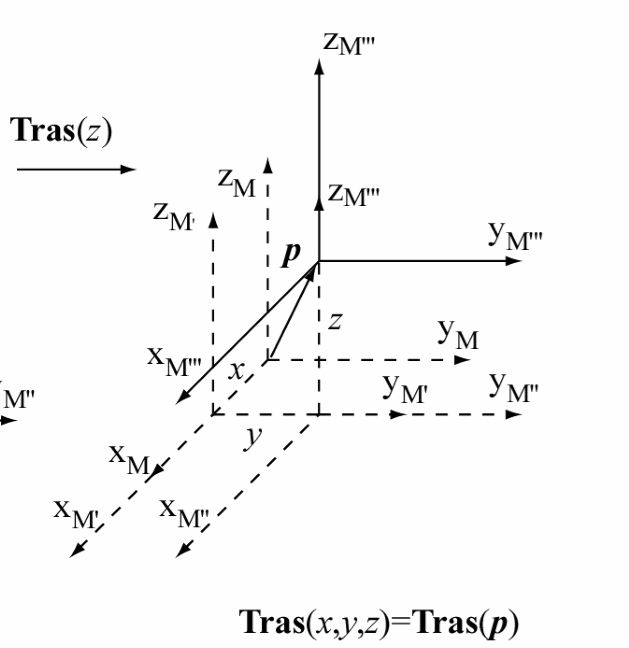

b. Rotación en el eje 𝑋  

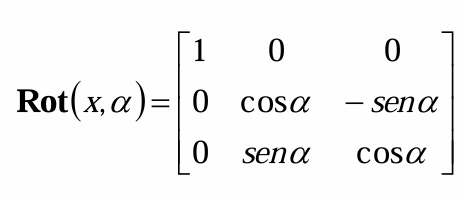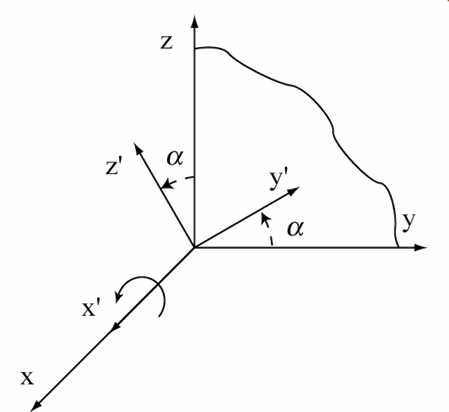

c. Rotación en el eje 𝑌   

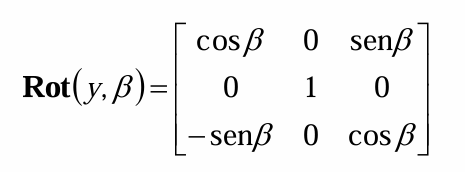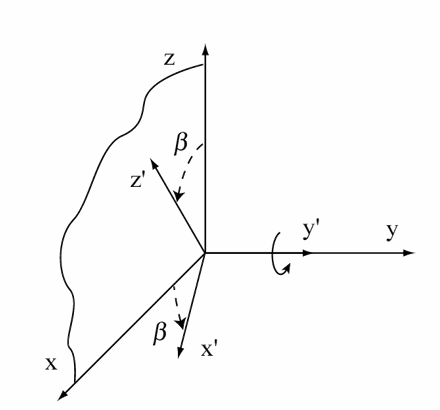

d. Rotación en el eje 𝑍.  

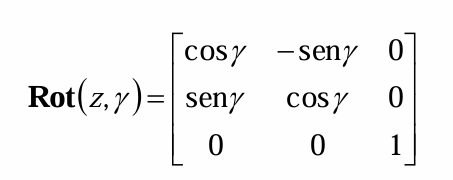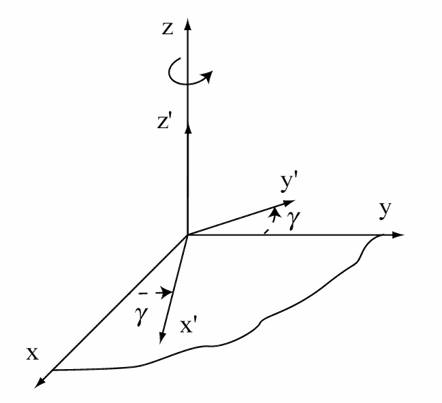

### Ejercicio 4 (obligatorio)

En la siguiente figura se observa el vector 𝑎 respecto del sistema {𝑀}.  El punto 𝑀 respecto de {𝑂} es 𝑝 𝑂 𝑀=(7,4).  

a. Halle, por el método que elija, el ángulo de rotación del sistema {𝑀} respecto de {𝑂}.  

b. Exprese la matriz de transformación homogénea que describe la posición y orientación  del sistema {𝑀} respecto de {𝑂}.  

c. Use la transformación hallada para representar el vector 𝑎 respecto del sistema {𝑂}.  Verifique gráficamente el resultado.   

### Ejercicio 5

Escriba la matriz de transformación homogénea que representa la posición y  orientación del sistema {𝑀} respecto de {𝑂} para cada caso. Realice un gráfico donde se  aprecie la diferencia.  

a. El sistema {𝑀} giró 45° respecto del eje 𝑌𝑀, luego se trasladó un vector ${}^{M}\rho$ = (0 0 1)

b. El sistema {𝑀} se trasladó un vector 𝑝 𝑀 =(0,0,1).  ${}^{M}\rho$ = (0,0,1), luego giró 45° respecto del eje $Y_M$.

### Ejercicio 6

Exprese el vector $\degree \rho =\left\lbrack \begin{array}{ccc}
0\ldotp 5 & 0 & 1
\end{array}\right\rbrack$ respecto del sistema {𝑀} de cada caso del  ejercicio anterior.  

### Ejercicio 7

Analizar la siguiente transformación compuesta e indicar V o F. Considere que 𝑇  representa la posición y orientación de un sistema de referencia {𝑀} respecto de otro sistema  de referencia {𝑂}.


$$T=T\;{\textrm{Rot}}_X \left(a\right)*\textrm{Ttras}\left(0,2,0\right)*T\;{\textrm{Rot}}_Y \left(\beta \;\right)$$


a. El sistema {𝑀} sufrió una rotación 𝛼 respecto de $X_O$, luego una traslación de 2  unidades sobre el eje $Y_O$, y finalmente una rotación 𝛽 respecto de este mismo eje.  

b. El sistema {𝑀} sufrió una rotación 𝛼 respecto de $X_M$, luego una traslación de 2  unidades sobre el eje $Y_M$, y finalmente una rotación 𝛽 respecto de este mismo eje.

c. Un vector 𝑝 expresado en {𝑂} puede expresarse en {𝑀} realizando el producto: ${}^{M}\rho = T \cdot \rho$

d. Un vector 𝑝 expresado en {𝑀} puede expresarse en {𝑂} realizando el producto: ${}^{O}\rho = T \cdot \rho$

### Ejercicio 8

En función de las siguientes matrices escritas en forma simbólica halle la expresión  correcta para cada caso: -  � � 𝑂 𝑀: matriz de trasformación homogénea del sistema {𝑀} respecto de {𝑂}. - - -  � � 𝑀 𝐴: matriz de trasformación homogénea del sistema {𝐴} respecto de {𝑀}.  � � 𝐴 𝐵: matriz de trasformación homogénea del sistema {𝐵} respecto de {𝐴}.   � � 𝐹: matriz de trasformación homogénea del sistema {𝐹} respecto de {𝑂}.  � � = 𝑇 ROBOTICA I  Trabajo Práctico N°2 -  � � 𝐹 𝐷: matriz de trasformación homogénea del sistema {𝐷} respecto de {𝐹}.  

1. {𝐵} respecto de {𝑂}:  

2. {𝐹} respecto de {𝐵}:  

3. {𝐵} respecto de {𝐷}: